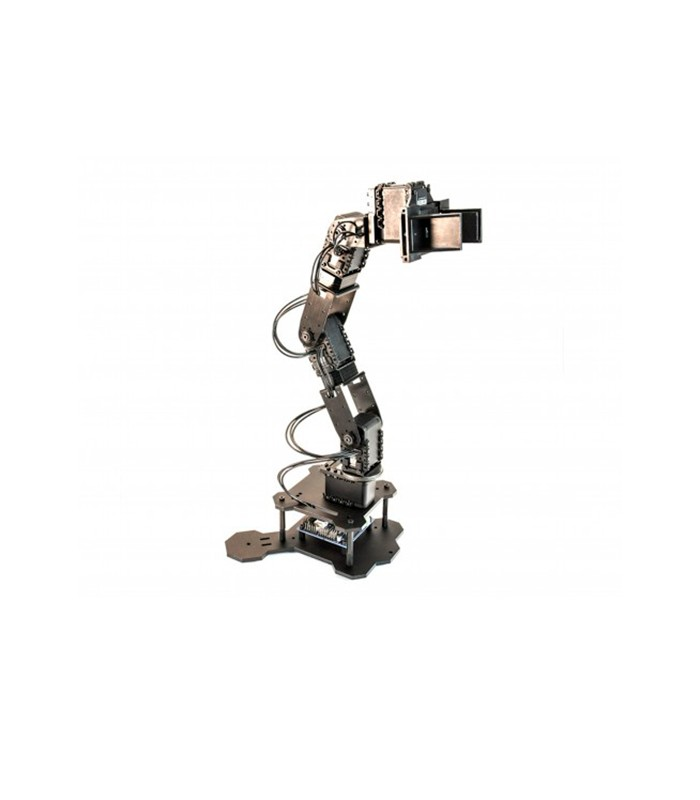

clear
clearvars
syms theta_1 theta_2 theta_3 theta_4 
L=[0.145 0.107 0.107 0.09]*100

L =    14.5000   10.7000   10.7000    9.0000


DHsym=[0, L(1), 0, sym(pi)/2, 0, 0;
       0, 0, L(2), 0, 0, sym(pi)/2;
       0, 0, L(3),0, 0, 0;
       0, 0, 0, 0 , 0, 0]

$$DHsym = \left(\begin{array}{cccccc} 0 & \frac{29}{2} & 0 & \frac{\pi }{2} & 0 & 0\\ 0 & 0 & \frac{107}{10} & 0 & 0 & \frac{\pi }{2}\\ 0 & 0 & \frac{107}{10} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


q_sym=[theta_1 theta_2 theta_3 theta_4]

$$q\_sym = \left(\begin{array}{cccc} \theta_{1} & \theta_{2} & \theta_{3} & \theta_{4} \end{array}\right)$$

A_1=trotz(q_sym(1)+DHsym(1,end))*transl(0,0,DHsym(1,2))*transl(DHsym(1,3),0,0)*trotx(DHsym(1,4))

$$A\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{29}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2=trotz(q_sym(2)+DHsym(2,end))*transl(0,0,DHsym(2,2))*transl(DHsym(2,3),0,0)*trotx(DHsym(2,4))

$$A\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\frac{\pi }{2}\right) & -\sin\left(\theta_{2}+\frac{\pi }{2}\right) & 0 & \frac{107\,\cos\left(\theta_{2}+\frac{\pi }{2}\right)}{10}\\ \sin\left(\theta_{2}+\frac{\pi }{2}\right) & \cos\left(\theta_{2}+\frac{\pi }{2}\right) & 0 & \frac{107\,\sin\left(\theta_{2}+\frac{\pi }{2}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3=trotz(q_sym(3)+DHsym(3,end))*transl(0,0,DHsym(3,2))*transl(DHsym(3,3),0,0)*trotx(DHsym(3,4))

$$A\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{107\,\cos\left(\theta_{3}\right)}{10}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{107\,\sin\left(\theta_{3}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_4=trotz(q_sym(4)+DHsym(4,end))*transl(0,0,DHsym(4,2))*transl(DHsym(4,3),0,0)*trotx(DHsym(4,4))

$$A\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & 0\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A=simplify(A_1*A_2*A_3*A_4)

$$A = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{2}-\sigma_{3} & -\sigma_{5}-\sigma_{4} & \sin\left(\theta_{1}\right) & -\frac{107\,\cos\left(\theta_{1}\right)\,\sigma_{1}}{10}\\ \sigma_{5}-\sigma_{4} & \sigma_{2}-\sigma_{3} & -\cos\left(\theta_{1}\right) & -\frac{107\,\sin\left(\theta_{1}\right)\,\sigma_{1}}{10}\\ \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) & -\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) & 0 & \frac{107\,\cos\left(\theta_{2}+\theta_{3}\right)}{10}+\frac{107\,\cos\left(\theta_{2}\right)}{10}+\frac{29}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}\right)+\sin\left(\theta_{2}\right)\\ \sigma_{2}=\frac{\sin\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{3}=\frac{\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{4}=\frac{\cos\left(\theta_{2}-\theta_{1}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{5}=\frac{\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2} \end{array}$$

q_1=[0 0 0 0];
A_q_1=double(subs(A,q_sym,q_1))

A_q_1 =          0   -1.0000         0         0
         0         0   -1.0000         0
    1.0000         0         0   35.9000
         0         0         0    1.0000



DH=[0, L(1), 0, sym(pi/2), 0, 0;
       0, 0, sym(L(2)), 0, 0, 0;
       0, 0, sym(L(3)),0, 0, 0;
       0, 0, 0, 0 , 0, 0]

$$DH = \left(\begin{array}{cccccc} 0 & \frac{29}{2} & 0 & \frac{\pi }{2} & 0 & 0\\ 0 & 0 & \frac{107}{10} & 0 & 0 & 0\\ 0 & 0 & \frac{107}{10} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


Li(1)=Link(DH(1,:));
Li(2)=Link(DH(2,:));
Li(3)=Link(DH(3,:));
Li(4)=Link(DH(4,:));
q_1=[0 0 0 0];
Robot_q_1=SerialLink(Li,'name','Robot');
Robot_q_1.plot(q_1,workspace)
%Robot_q_1.tool = [1 0 0 L(4); 0 0 -1 0; 0 1 0 0; 0 0 0 1];
H_40=simplify(Robot_q_1.A([1 2 3 4],[theta_1 theta_2 theta_3 theta_4]),"Steps",200)

$$H\_40 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(\theta_{1}\right) & -\sigma_{1}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \frac{107\,\cos\left(\theta_{1}\right)\,\sigma_{3}}{10}\\ \sigma_{2}\,\sin\left(\theta_{1}\right) & -\sigma_{1}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \frac{107\,\sin\left(\theta_{1}\right)\,\sigma_{3}}{10}\\ \sigma_{1} & \sigma_{2} & 0 & \frac{107\,\sin\left(\theta_{2}+\theta_{3}\right)}{10}+\frac{107\,\sin\left(\theta_{2}\right)}{10}+\frac{29}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{2}\right) \end{array}$$


trplot(eye(4),'rgb','arrow','length',15,'frame','0')
axis([repmat([-50 50],1,2) 0 60])
Robot_q_1.teach()
M = eye(4);
for i=1:Robot_q_1.n
    M = M * Li(i).A(q_1(i));
    trplot(M,'rgb','arrow','frame',num2str(i),'length',15)
end
hold off
Robot_q_1.fkine(q_1)